# Heat equation in a 2D trapezoid

## Cartesian case

Equation : $\Delta u =0$

Domain : $0<x<1, 0<y<2(1-x) $

Boundary cond. : $u=1, y=2(1-x); u=0\ \text{otherwise}$

nx=21;
main_head_2d_trapz_cartesian;

Elapsed time is 0.000671 seconds.


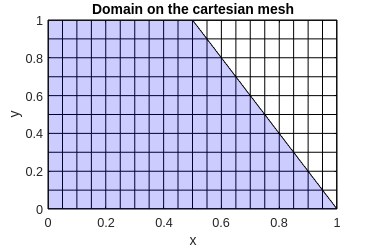

a=load("dataCart-21.mat");

[X,Y]=meshgrid(a.x,a.y);
plot(X,Y,'k'); hold on;
plot(X',Y','k');
fill([0 1 0.5 0 0],[0 0 1 1 0],'blue','FaceAlpha',0.2);
title("Domain on the cartesian mesh");
xlabel('x'); ylabel('y');

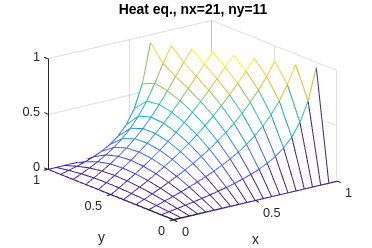


clf;
mesh(a.x,a.y,a.uPhys);
xlabel('x'); ylabel('y'); title("Heat eq., nx="+num2str(nx)+", ny="+num2str(ny));



nx=81;
main_head_2d_trapz_cartesian;

Elapsed time is 0.005866 seconds.


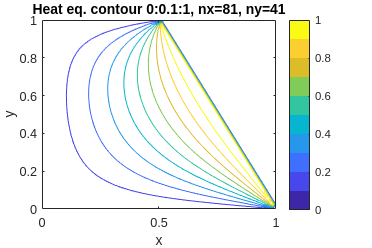

a=load("dataCart-81.mat");
contour(a.x,a.y,a.uPhys,[0:0.1:1]); colorbar(); colormap(parula(10))
xlabel('x'); ylabel('y'); title("Heat eq. contour 0:0.1:1, nx="+num2str(nx)+", ny="+num2str(ny));

## Modified coordinate

Transform : $(x,y) \to (\theta,z)$


$$x=(2-z)\tan(\theta), \\
y=z$$


Equation : $0=\frac{\partial^2 u }{\partial \theta^2}\left[\frac{\cos(\theta)^2}{(L-z)}\right]^2\\
-\frac{\partial u }{\partial \theta}\frac{\cos(\theta)^2}{(L-z)}\frac{2\sin(\theta)\cos(\theta)}{(L-z)}\\
+\frac{\partial^2 u }{\partial z^2}\\
+\frac{\partial u }{\partial \theta}\frac{\sin(\theta)\cos(\theta)}{(L-z)^2}\\
+\frac{\partial^2 u }{\partial \theta\partial z}\frac{2\sin(\theta)\cos(\theta)}{(L-z)}\\
+\frac{\partial u }{\partial \theta}\frac{\cos(2\theta)\sin(\theta)\cos(\theta)}{(L-z)^2}\\
+\frac{\partial^2 u }{\partial \theta^2}\left[\frac{\sin(\theta)\cos(\theta)}{(L-z)}\right]^2$

Domain : $0<z<1, 0<\theta<\tan^{-1}(0.5) $

Boundary cond. : $u=1, \theta=\tan^{-1}(0.5);\ u=0\ \text{otherwise}$

nx=21;
diff_2d_mod;

Elapsed time is 0.000622 seconds.


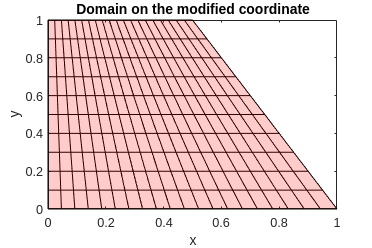

a=load("dataMod-21.mat");

X=a.X; Y=a.Y;
plot(X,Y,'k'); hold on;
plot(X',Y','k');
fill([0 1 0.5 0 0],[0 0 1 1 0],'red','FaceAlpha',0.2);
title("Domain on the modified coordinate");
xlabel('x'); ylabel('y');

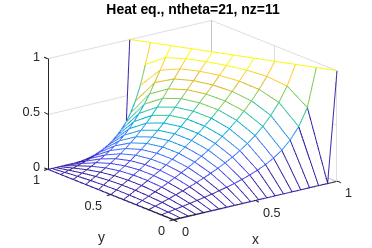



clf;
mesh(a.X,a.Y,a.uPhys);
xlabel('x'); ylabel('y'); title("Heat eq., ntheta="+num2str(nx)+", nz="+num2str(ny));

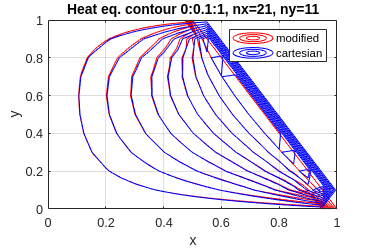


contour(a.X,a.Y,a.uPhys,[0:0.1:1],'r');
xlabel('x'); ylabel('y'); title("Heat eq. contour 0:0.1:1, nx="+num2str(nx)+", ny="+num2str(ny));
grid on; hold on;
a=load("dataCart-21.mat");
contour(a.x,a.y,a.uPhys,[0:0.1:1],'b');
legend("modified",'cartesian',"Location","northeast");


clf;
nx=81;
diff_2d_mod;

Elapsed time is 0.024575 seconds.


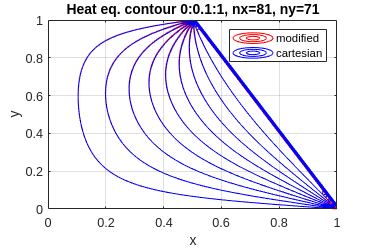

a=load("dataMod-81.mat");


contour(a.X,a.Y,a.uPhys,[0:0.1:1],'r');
xlabel('x'); ylabel('y'); title("Heat eq. contour 0:0.1:1, nx="+num2str(nx)+", ny="+num2str(ny));
grid on; hold on;
a=load("dataCart-81.mat");
contour(a.x,a.y,a.uPhys,[0:0.1:1],'b');
legend("modified",'cartesian',"Location","northeast");


clf;
nx=301;
diff_2d_mod;

Elapsed time is 0.422537 seconds.


main_head_2d_trapz_cartesian;

Elapsed time is 0.115084 seconds.


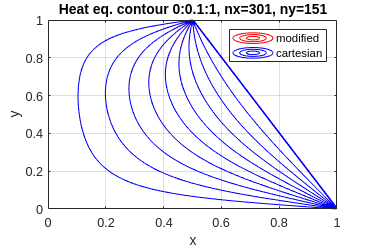


a=load("dataMod-301.mat");

contour(a.X,a.Y,a.uPhys,[0:0.1:1],'r');
xlabel('x'); ylabel('y'); title("Heat eq. contour 0:0.1:1, nx="+num2str(nx)+", ny="+num2str(ny));
grid on; hold on;

a=load("dataCart-301.mat");

contour(a.x,a.y,a.uPhys,[0:0.1:1],'b');
legend("modified",'cartesian',"Location","northeast");